# MATLAB Pi Programming Sandbox

This is an example of working in MATLAB continuing from our classroom example with our classic pi case.

This is presented in "notebook" form which lets you share the results of your work with people who don't have the [rather expensive] MATLAB license and more importantly lets us "serve" this document online as an HTML web document.  R has a similer function when you use the commecial (free versions available) of R-Studio and also the Jupyter notebook tools.

The "grey" areas below are MATLAB code.  The not-grey (white) areas are text comments and also model output (you can tell by the difference in the fonts).  [Also inside the grey "code" area are comments shown in green with the "%" signs.]

This includes some extras such as tying the errors between $\pi$ and the estimated values we calculate to the number of significant figures using the Scarborough from the "Errors" Lecture.

We also will demonstrate a more detailed form of text output where you can control the number of significant figures.

If you haven't had a formal computer programming class don't panic here.  From Lecture 2 (Pseudocode), you saw that programming structures in different languages tend to have a similar "look-n-feel" or at least are marginally intuitive.  Try to follow along.

And away we go!  

Normaly you start by descrining what you are going to do.  It also sometimes helps to cite any literature you are using.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% Test program to show the relationship between significant figures
%    and error
%
% Program uses a numerical approximation pi using the "Trapezioidal
%   Rule" to estimate pi from your homework #1
%
% Program also uses the Scarborough (1966) formula for linking 
%  significant figures to percent error error.
%
% Scarborough, J. B., Numerical Mathematical Analysis, 6th ed.,
%    Johns Hopkins Press, Baltimore, MD, 1966.
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% Let's start by defining what the REAL answer is (or nearly is since
%    we are talking about pi
%

PI25DT = pi % lucky for us, pi is an intrinsic value in MATLAB

PI25DT = 3.1416

            % that is already in double precision 
            % [ so is the square root of 1 (i and j)  ]
            %
            % in other languates we may need to manually enter values
            % for pi
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


In your homework you were asked to do three specific runs through your $\pi$ pseudocode example in which you had *n* = 1, 2 and 3.  But since this is a computer program, we can run a LOT of iterations on the same general problem, we can do a lot more here.  Here we are *"only"* going to 100 iterations.


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% We now will set the total number of iterations that we'll run through
% 
% We will actually be calculating PI for a range of iterations starting 
%    with n=1 and then going all the way through n=nmax
%

nmax               = 100;            % maximum value of "n" that we'll try'

%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


Another important step in many programming languates is to set up your variables and arrays in which you are storing your results ahead of time.  

Notice after we initialize the first array, all we have to do for the others is "clone" the first one and use a little bit of Math-Fu (basically just multiplying each array by zero) to initialize them too.


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% This section creates arrays (or vectors depending on what you want to
%    call them for.  
% 
% The first line we are acutally creating the equivalent of a "Range" that
%     have in Matchad Prime.  The good news is that MATLAB doesn't treat 
%     these "range" variables differently than any other array in MATLAB 
%     (unlike Mathcad)
%

n_storage_array    = 1:nmax;            % values of "n"  can you guess what this does?
pi_storage_array   = n_storage_array*0; % initialize our output pi array to zero
e_pi_storage_array = n_storage_array*0; % initialize our output pi error array to zero
s_pi_storage_array = n_storage_array*0; % initialize our output sigfig array to zero

%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

As a reminder, this is how we calculated $\pi$ here in "mathese"


$$\pi =\int_0^1 \frac{4}{1+x^2 }\mathrm{dx}$$


We will attack this by callculating creating Riemann Sums 


$$\pi \approx \mathrm{Δ x}\sum_{n=1}^{N} \frac{4}{\left\lbrace 1+\left\lbrack \mathrm{Δ x}{\left(n-\frac{1}{2}\right)}^2 \right\rbrack \right\rbrace }$$
   

where $\Delta x=\frac{1}{N}$  

This is basically a Reimann Sum method as illustrated below from your notes.

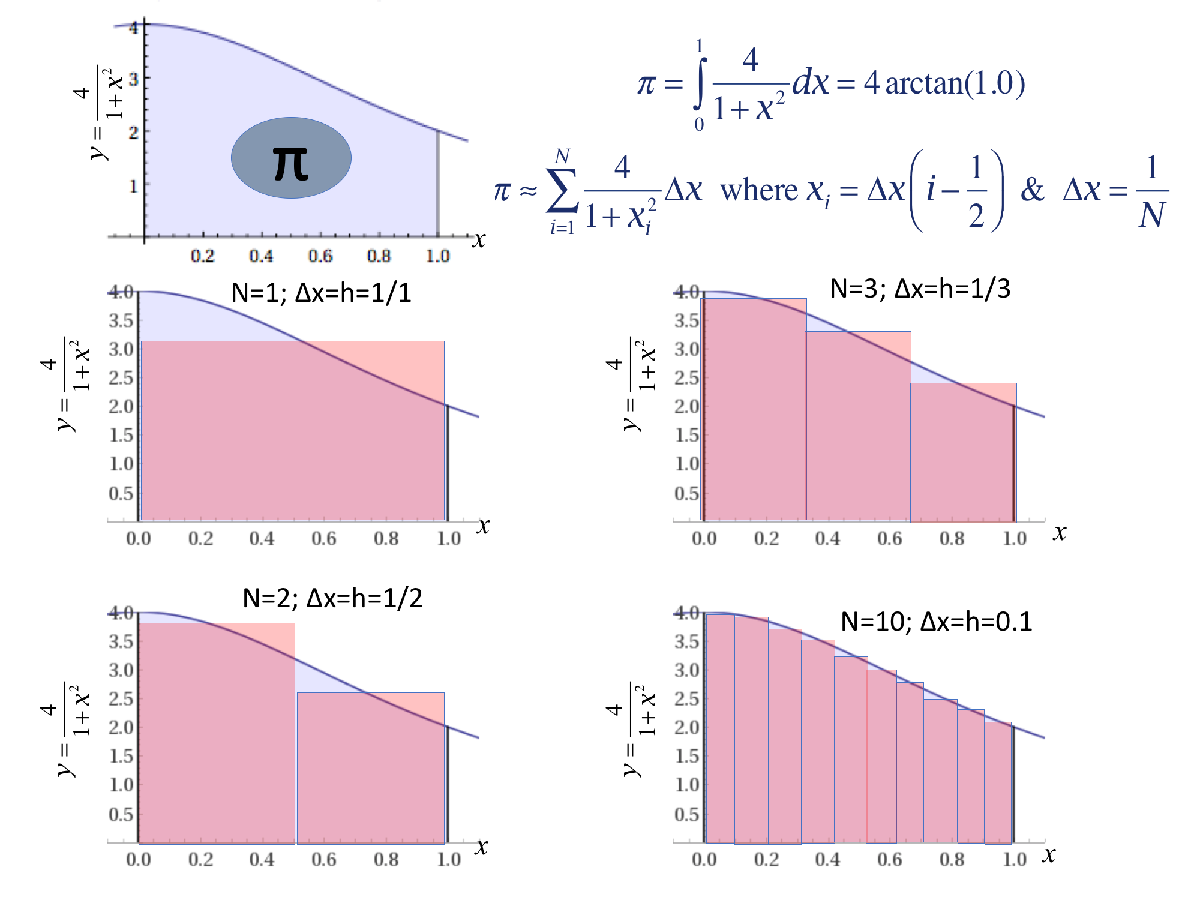

(and in the code as is with Differential Equations, the traditional single-letter convention for assigning the $\Delta x$ is "*h*" so it's used in the code below.)

To do this, unlike your homework where you start over from scratch each time.  We are sneaking in another loop, wrapped around the meat and potatoes of your homework's pseudocode.  This will let us collect all of our estiamtes of $\pi$.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% Loop for a variety of values of "N" like you did in your first homework
%   but this time we are doing it more than just 3 times!

for N = 1:nmax  

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %
    % Pi is approxinated iteratively for N procedural steps.
    % The more steps, the closer the estimate of pi approaches
    % the true value
    %
    % And here si the "meat and potatoes" of your Pseudocode homework!
    %   one major difference is that I'm using little-n (MATLAB is
    %   "case senstive") rather than "i" since as we'll see later in the 
    %   class, "i" in MATLAB is a shortcut for sqrt(-1).

    h = 1.0 / N;   
    sum  = 0.0;  % you will have to reset this summing value this everty time.
    for n = 1:N    
        x = h * (n - 0.5);                
        sum = sum + 4.d0 / (1.d0 + x*x);
    end
    est_pi = h*sum;

    %
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    

With this done inside the outer-loop for whatever value of *N* you are using, you now have a brand new value of $\pi$.  As *N* (the number of Reimann Sum Boxes) gets bigger, the smaller the $\Delta x$, and therefore, your estimate of $\pi$ will be more and more accurate.

And wirth this you can check your value of $\pi$ with the value that comes with MATLAB whcih for us is our benchmark value .  Here we use both a "plain" error and also a percentage error based on the our "benchmark" value of $\pi$.

    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %
    % error of pi is calculated.  
    %

    error    = est_pi - PI25DT;
    perc_err = error/PI25DT * 100.;

    %
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    
    

And here is the Scarborough formula for linking precision error.  


$$\mathrm{Error}\left(%\right)\simeq \frac{1}{2}{10}^{2-\mathrm{SigFigs}}$$


A little Algebra- and Calc-2-Fu will "invert" the original formula so that...


$$\mathrm{SigFigs}\simeq 2-{\mathrm{log}}_{10} \left\lbrack \mathrm{2 Error( % )}\right\rbrack$$


    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %
    % We used a formula early in teh class to tie error to precision
    %
    % Scarborough formula for guestimating the percent error as a
    % function of the number of significant figures is "inverted"
    % so that we're solving for sig figs rather than the percent
    % error.  Notice also what I have to do with the "log" command.
    % in most languates "plain" "log" is the natural log.
    %

    Sigfig = 2-log10(perc_err*2);

    %
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

And we can now store our values of$\pi$, error and the guestimated numbner of significant figures we should expect for a given error.

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %
    % store our error values in our "back pocket" for the end
    %

    pi_storage_array(N)   = est_pi;
    e_pi_storage_array(N) =  error;
    s_pi_storage_array(N) = Sigfig;

    %
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Here we plot things out to the screen.  

Now while most langauges loops and if-then-else blocks will be *somewhat* intuitive, making nice print formats is ... more passive-agressive from language to language.  MATLAB leverages elements of the C-family of languates.  

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %
    % And now we print out output to the screen.  The strange percent
    %   codes show the look-n-feel of the displayed floating and integer
    %   values.  The "..." lets me continue to the next line to do a
    %   single command
    %
    % This use of Fprint follows Savannah's question on how to have more
    %   control over the format.  C-skateers may recognize the formating
    %   a following C computer language conventions.
    %
    % Your onlie help should have a description of this command here...
    %   https://www.mathworks.com/help/simulink/slref/fprintf.html

[https://www.mathworks.com/help/simulink/slref/fprintf.html](https://www.mathworks.com/help/simulink/slref/fprintf.html)

    % 
    % The output specific C-formating guidance can be found here...
    %   https://www.mathworks.com/help/MATLAB/MATLAB_prog/formatting-strings.html

[https://www.mathworks.com/help/MATLAB/MATLAB_prog/formatting-strings.html](https://www.mathworks.com/help/matlab/matlab_prog/formatting-strings.html)

    %
    

    fprintf('n= %4.0i, est_pi= %15.12f, Error=%11.8f,  %%Error= %11.8f%%,  Estimated SF=%3.1f \n', ...
                n,        est_pi,          error,           perc_err,           Sigfig);

    %
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

end

n=    1, est_pi=  3.200000000000, Error= 0.05840735,  %Error=  1.85916358%,  Estimated SF=1.4 


n=    2, est_pi=  3.162352941176, Error= 0.02076029,  %Error=  0.66082048%,  Estimated SF=1.9 


n=    3, est_pi=  3.150849209866, Error= 0.00925656,  %Error=  0.29464534%,  Estimated SF=2.2 


n=    4, est_pi=  3.146800518394, Error= 0.00520786,  %Error=  0.16577149%,  Estimated SF=2.5 


n=    5, est_pi=  3.144925864003, Error= 0.00333321,  %Error=  0.10609938%,  Estimated SF=2.7 


n=    6, est_pi=  3.143907427222, Error= 0.00231477,  %Error=  0.07368153%,  Estimated SF=2.8 


n=    7, est_pi=  3.143293317527, Error= 0.00170066,  %Error=  0.05413381%,  Estimated SF=3.0 


n=    8, est_pi=  3.142894729592, Error= 0.00130208,  %Error=  0.04144637%,  Estimated SF=3.1 


n=    9, est_pi=  3.142621456558, Error= 0.00102880,  %Error=  0.03274782%,  Estimated SF=3.2 


n=   10, est_pi=  3.142425985001, Error= 0.00083333,  %Error=  0.02652576%,  Estimated SF=3.3 


n=   11, est_pi=  3.142281357739, Error= 0.00068870,  %Error=  0.02192213%,  Estimated SF=3.4 


n=   12, est_pi=  3.142171356650, Error= 0.00057870,  %Error=  0.01842069%,  Estimated SF=3.4 


n=   13, est_pi=  3.142085749839, Error= 0.00049310,  %Error=  0.01569574%,  Estimated SF=3.5 


n=   14, est_pi=  3.142017823403, Error= 0.00042517,  %Error=  0.01353358%,  Estimated SF=3.6 


n=   15, est_pi=  3.141963023791, Error= 0.00037037,  %Error=  0.01178925%,  Estimated SF=3.6 


n=   16, est_pi=  3.141918174309, Error= 0.00032552,  %Error=  0.01036165%,  Estimated SF=3.7 


n=   17, est_pi=  3.141881004145, Error= 0.00028835,  %Error=  0.00917848%,  Estimated SF=3.7 


n=   18, est_pi=  3.141849855179, Error= 0.00025720,  %Error=  0.00818698%,  Estimated SF=3.8 


n=   19, est_pi=  3.141823493807, Error= 0.00023084,  %Error=  0.00734787%,  Estimated SF=3.8 


n=   20, est_pi=  3.141800986893, Error= 0.00020833,  %Error=  0.00663146%,  Estimated SF=3.9 


n=   21, est_pi=  3.141781618042, Error= 0.00018896,  %Error=  0.00601493%,  Estimated SF=3.9 


n=   22, est_pi=  3.141764829881, Error= 0.00017218,  %Error=  0.00548054%,  Estimated SF=4.0 


n=   23, est_pi=  3.141750183507, Error= 0.00015753,  %Error=  0.00501433%,  Estimated SF=4.0 


n=   24, est_pi=  3.141737329506, Error= 0.00014468,  %Error=  0.00460518%,  Estimated SF=4.0 


n=   25, est_pi=  3.141725986915, Error= 0.00013333,  %Error=  0.00424413%,  Estimated SF=4.1 


n=   26, est_pi=  3.141715927745, Error= 0.00012327,  %Error=  0.00392394%,  Estimated SF=4.1 


n=   27, est_pi=  3.141706965428, Error= 0.00011431,  %Error=  0.00363866%,  Estimated SF=4.1 


n=   28, est_pi=  3.141698946103, Error= 0.00010629,  %Error=  0.00338340%,  Estimated SF=4.2 


n=   29, est_pi=  3.141691741973, Error= 0.00009909,  %Error=  0.00315408%,  Estimated SF=4.2 


n=   30, est_pi=  3.141685246180, Error= 0.00009259,  %Error=  0.00294731%,  Estimated SF=4.2 


n=   31, est_pi=  3.141679368815, Error= 0.00008672,  %Error=  0.00276023%,  Estimated SF=4.3 


n=   32, est_pi=  3.141674033796, Error= 0.00008138,  %Error=  0.00259041%,  Estimated SF=4.3 


n=   33, est_pi=  3.141669176392, Error= 0.00007652,  %Error=  0.00243580%,  Estimated SF=4.3 


n=   34, est_pi=  3.141664741247, Error= 0.00007209,  %Error=  0.00229462%,  Estimated SF=4.3 


n=   35, est_pi=  3.141660680800, Error= 0.00006803,  %Error=  0.00216537%,  Estimated SF=4.4 


n=   36, est_pi=  3.141656954000, Error= 0.00006430,  %Error=  0.00204675%,  Estimated SF=4.4 


n=   37, est_pi=  3.141653525272, Error= 0.00006087,  %Error=  0.00193761%,  Estimated SF=4.4 


n=   38, est_pi=  3.141650363654, Error= 0.00005771,  %Error=  0.00183697%,  Estimated SF=4.4 


n=   39, est_pi=  3.141647442106, Error= 0.00005479,  %Error=  0.00174397%,  Estimated SF=4.5 


n=   40, est_pi=  3.141644736923, Error= 0.00005208,  %Error=  0.00165786%,  Estimated SF=4.5 


n=   41, est_pi=  3.141642227256, Error= 0.00004957,  %Error=  0.00157798%,  Estimated SF=4.5 


n=   42, est_pi=  3.141639894708, Error= 0.00004724,  %Error=  0.00150373%,  Estimated SF=4.5 


n=   43, est_pi=  3.141637722996, Error= 0.00004507,  %Error=  0.00143460%,  Estimated SF=4.5 


n=   44, est_pi=  3.141635697667, Error= 0.00004304,  %Error=  0.00137014%,  Estimated SF=4.6 


n=   45, est_pi=  3.141633805853, Error= 0.00004115,  %Error=  0.00130992%,  Estimated SF=4.6 


n=   46, est_pi=  3.141632036072, Error= 0.00003938,  %Error=  0.00125358%,  Estimated SF=4.6 


n=   47, est_pi=  3.141630378050, Error= 0.00003772,  %Error=  0.00120081%,  Estimated SF=4.6 


n=   48, est_pi=  3.141628822571, Error= 0.00003617,  %Error=  0.00115129%,  Estimated SF=4.6 


n=   49, est_pi=  3.141627361350, Error= 0.00003471,  %Error=  0.00110478%,  Estimated SF=4.7 


n=   50, est_pi=  3.141625986923, Error= 0.00003333,  %Error=  0.00106103%,  Estimated SF=4.7 


n=   51, est_pi=  3.141624692549, Error= 0.00003204,  %Error=  0.00101983%,  Estimated SF=4.7 


n=   52, est_pi=  3.141623472130, Error= 0.00003082,  %Error=  0.00098098%,  Estimated SF=4.7 


n=   53, est_pi=  3.141622320138, Error= 0.00002967,  %Error=  0.00094432%,  Estimated SF=4.7 


n=   54, est_pi=  3.141621231550, Error= 0.00002858,  %Error=  0.00090966%,  Estimated SF=4.7 


n=   55, est_pi=  3.141620201799, Error= 0.00002755,  %Error=  0.00087689%,  Estimated SF=4.8 


n=   56, est_pi=  3.141619226719, Error= 0.00002657,  %Error=  0.00084585%,  Estimated SF=4.8 


n=   57, est_pi=  3.141618302507, Error= 0.00002565,  %Error=  0.00081643%,  Estimated SF=4.8 


n=   58, est_pi=  3.141617425686, Error= 0.00002477,  %Error=  0.00078852%,  Estimated SF=4.8 


n=   59, est_pi=  3.141616593071, Error= 0.00002394,  %Error=  0.00076202%,  Estimated SF=4.8 


n=   60, est_pi=  3.141615801738, Error= 0.00002315,  %Error=  0.00073683%,  Estimated SF=4.8 


n=   61, est_pi=  3.141615049003, Error= 0.00002240,  %Error=  0.00071287%,  Estimated SF=4.8 


n=   62, est_pi=  3.141614332397, Error= 0.00002168,  %Error=  0.00069006%,  Estimated SF=4.9 


n=   63, est_pi=  3.141613649643, Error= 0.00002100,  %Error=  0.00066833%,  Estimated SF=4.9 


n=   64, est_pi=  3.141612998642, Error= 0.00002035,  %Error=  0.00064760%,  Estimated SF=4.9 


n=   65, est_pi=  3.141612377456, Error= 0.00001972,  %Error=  0.00062783%,  Estimated SF=4.9 


n=   66, est_pi=  3.141611784291, Error= 0.00001913,  %Error=  0.00060895%,  Estimated SF=4.9 


n=   67, est_pi=  3.141611217487, Error= 0.00001856,  %Error=  0.00059091%,  Estimated SF=4.9 


n=   68, est_pi=  3.141610675504, Error= 0.00001802,  %Error=  0.00057366%,  Estimated SF=4.9 


n=   69, est_pi=  3.141610156915, Error= 0.00001750,  %Error=  0.00055715%,  Estimated SF=5.0 


n=   70, est_pi=  3.141609660392, Error= 0.00001701,  %Error=  0.00054134%,  Estimated SF=5.0 


n=   71, est_pi=  3.141609184701, Error= 0.00001653,  %Error=  0.00052620%,  Estimated SF=5.0 


n=   72, est_pi=  3.141608728693, Error= 0.00001608,  %Error=  0.00051169%,  Estimated SF=5.0 


n=   73, est_pi=  3.141608291295, Error= 0.00001564,  %Error=  0.00049776%,  Estimated SF=5.0 


n=   74, est_pi=  3.141607871510, Error= 0.00001522,  %Error=  0.00048440%,  Estimated SF=5.0 


n=   75, est_pi=  3.141607468405, Error= 0.00001481,  %Error=  0.00047157%,  Estimated SF=5.0 


n=   76, est_pi=  3.141607081106, Error= 0.00001443,  %Error=  0.00045924%,  Estimated SF=5.0 


n=   77, est_pi=  3.141606708799, Error= 0.00001406,  %Error=  0.00044739%,  Estimated SF=5.0 


n=   78, est_pi=  3.141606350719, Error= 0.00001370,  %Error=  0.00043599%,  Estimated SF=5.1 


n=   79, est_pi=  3.141606006151, Error= 0.00001335,  %Error=  0.00042503%,  Estimated SF=5.1 


n=   80, est_pi=  3.141605674423, Error= 0.00001302,  %Error=  0.00041447%,  Estimated SF=5.1 


n=   81, est_pi=  3.141605354906, Error= 0.00001270,  %Error=  0.00040430%,  Estimated SF=5.1 


n=   82, est_pi=  3.141605047006, Error= 0.00001239,  %Error=  0.00039449%,  Estimated SF=5.1 


n=   83, est_pi=  3.141604750169, Error= 0.00001210,  %Error=  0.00038505%,  Estimated SF=5.1 


n=   84, est_pi=  3.141604463869, Error= 0.00001181,  %Error=  0.00037593%,  Estimated SF=5.1 


n=   85, est_pi=  3.141604187615, Error= 0.00001153,  %Error=  0.00036714%,  Estimated SF=5.1 


n=   86, est_pi=  3.141603920942, Error= 0.00001127,  %Error=  0.00035865%,  Estimated SF=5.1 


n=   87, est_pi=  3.141603663411, Error= 0.00001101,  %Error=  0.00035045%,  Estimated SF=5.2 


n=   88, est_pi=  3.141603414609, Error= 0.00001076,  %Error=  0.00034253%,  Estimated SF=5.2 


n=   89, est_pi=  3.141603174147, Error= 0.00001052,  %Error=  0.00033488%,  Estimated SF=5.2 


n=   90, est_pi=  3.141602941656, Error= 0.00001029,  %Error=  0.00032748%,  Estimated SF=5.2 


n=   91, est_pi=  3.141602716787, Error= 0.00001006,  %Error=  0.00032032%,  Estimated SF=5.2 


n=   92, est_pi=  3.141602499210, Error= 0.00000985,  %Error=  0.00031340%,  Estimated SF=5.2 


n=   93, est_pi=  3.141602288615, Error= 0.00000964,  %Error=  0.00030669%,  Estimated SF=5.2 


n=   94, est_pi=  3.141602084705, Error= 0.00000943,  %Error=  0.00030020%,  Estimated SF=5.2 


n=   95, est_pi=  3.141601887200, Error= 0.00000923,  %Error=  0.00029391%,  Estimated SF=5.2 


n=   96, est_pi=  3.141601695835, Error= 0.00000904,  %Error=  0.00028782%,  Estimated SF=5.2 


n=   97, est_pi=  3.141601510358, Error= 0.00000886,  %Error=  0.00028192%,  Estimated SF=5.2 


n=   98, est_pi=  3.141601330530, Error= 0.00000868,  %Error=  0.00027620%,  Estimated SF=5.3 


n=   99, est_pi=  3.141601156124, Error= 0.00000850,  %Error=  0.00027064%,  Estimated SF=5.3 


n=  100, est_pi=  3.141600986923, Error= 0.00000833,  %Error=  0.00026526%,  Estimated SF=5.3 



%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Finally we can make some plots.  While in Mathcad the graphing process is Mouse-and-Menu centered.  MATLAB is written as a series of commands.

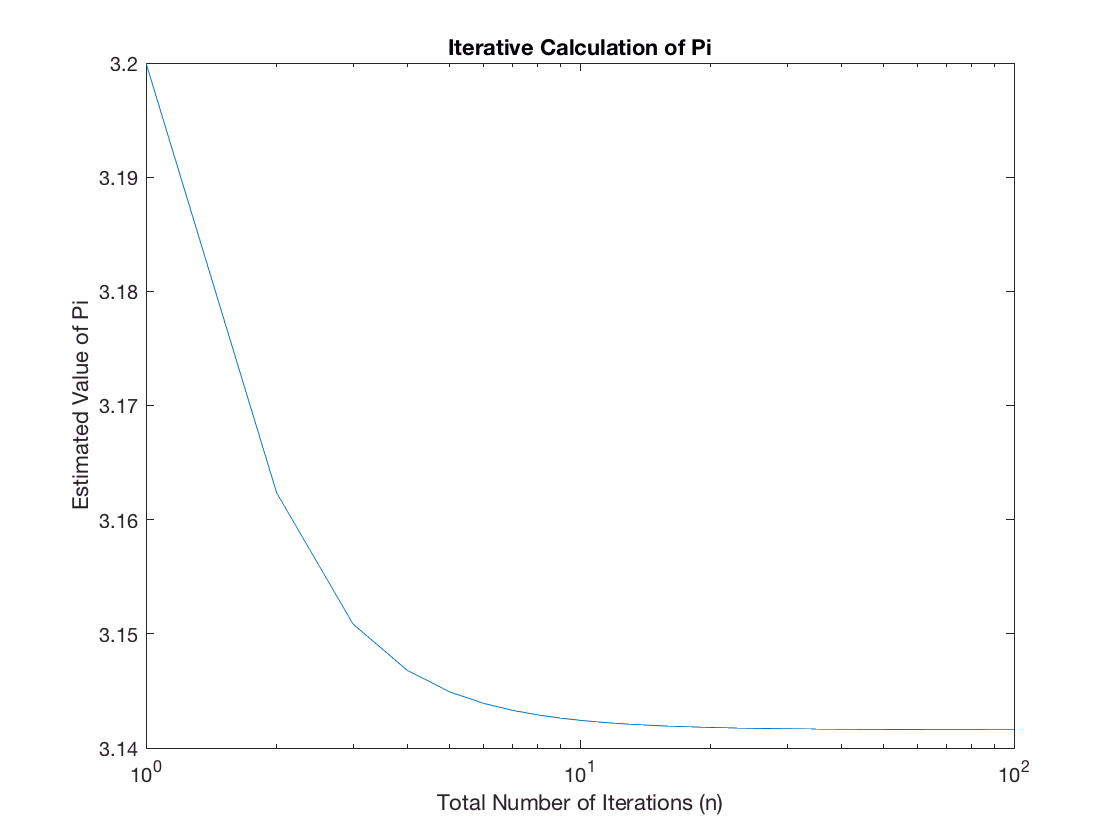

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% Some simple plots (including log, semilog and traditional linear plots)
%

figure;                                        % new figure
semilogx(n_storage_array, pi_storage_array);   % make a plot with log on the x
   title('Iterative Calculation of Pi');       % you will get docked if you
   xlabel('Total Number of Iterations (n)');   %    don't label your graph
   ylabel('Estimated Value of Pi');            %    axes and title them.

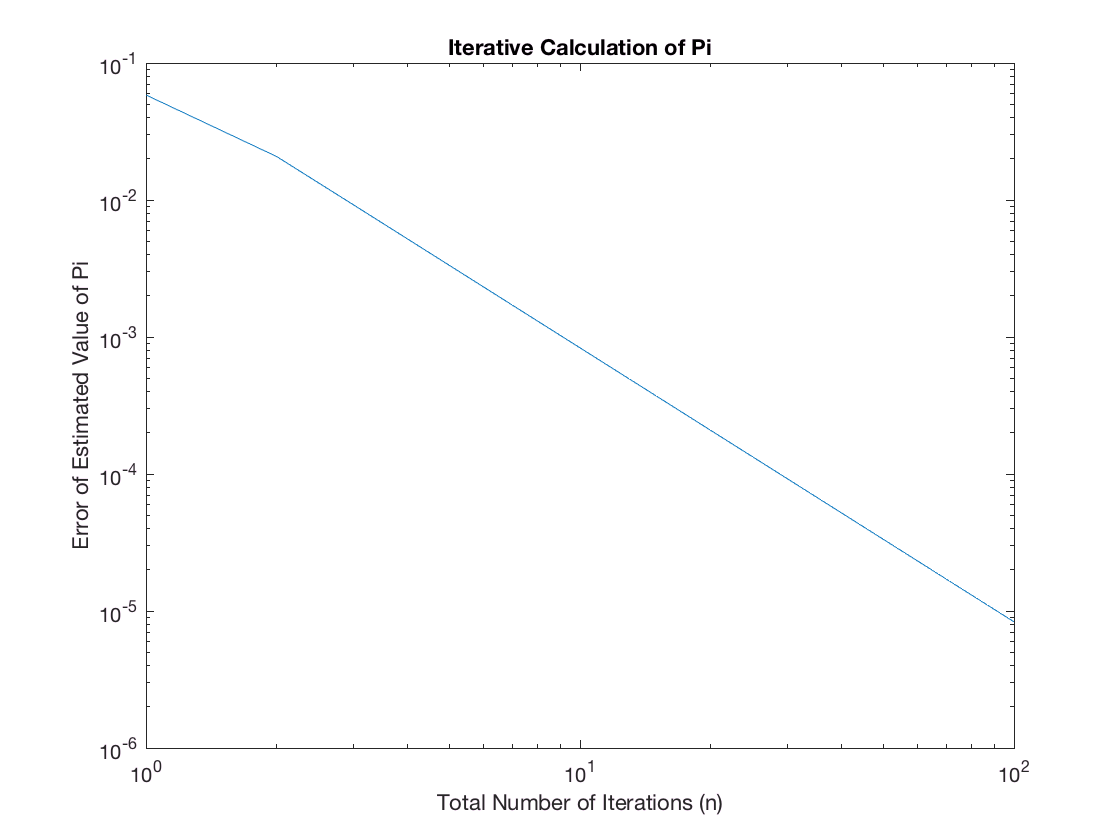


figure;
loglog(n_storage_array, e_pi_storage_array); % this time it's a log-log
   title('Iterative Calculation of Pi');
   xlabel('Total Number of Iterations (n)');
   ylabel('Error of Estimated Value of Pi');

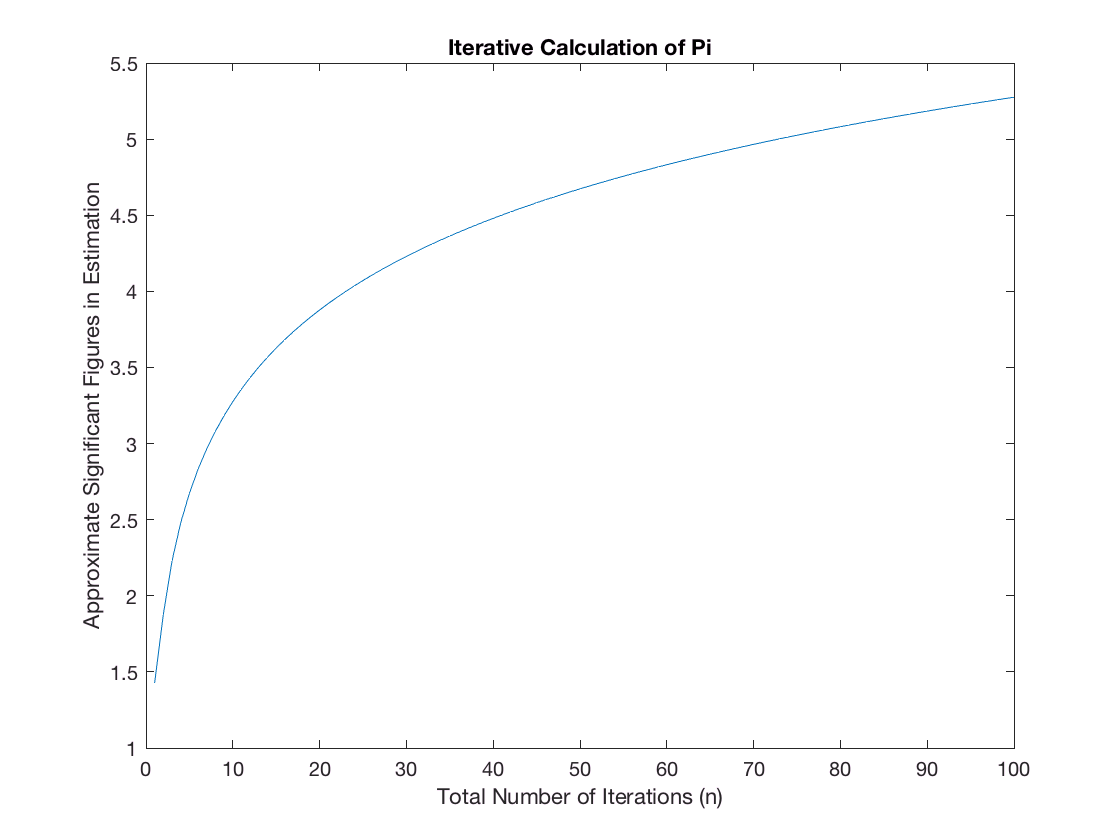

   
figure;
plot(n_storage_array, s_pi_storage_array); % and finally a plain old plot
   title('Iterative Calculation of Pi');
   xlabel('Total Number of Iterations (n)');
   ylabel('Approximate Significant Figures in Estimation');

%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

So to conclude, don't worry if you couldn't follow this through the first time.  As with walking through pseudo-code it takes practice.

We'll officially start working with MATLAB towards the close of the semester.